# Gaussian processes

Here we will study Gaussian processes or random fields. We simulate spatial data, perform parameter estimation and prediction (Kriging).

## Task 1

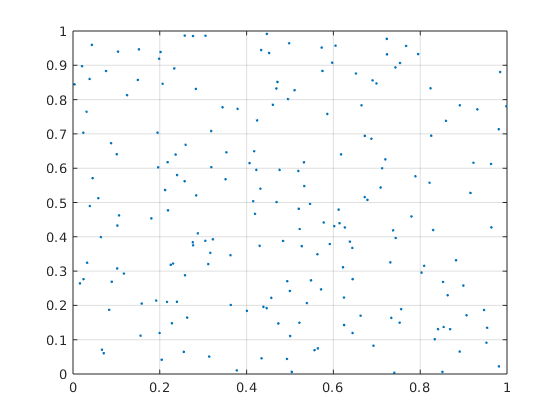

clc
close all
clear variables

m = 200;       % Number of measurments
sigma2 = 1;    % Covariance parameter
eta = 10;      % Covariance parameter
tau2 = 0.05^2; % Covariance parameter (Measurment Noise std)
alpha_true = 1;     % Regression parameter (Mean parameter)
theta_true = [sigma2; eta; tau2];

s_meas = rand(200,2); % locations.
figure
plot(s_meas(:,1),s_meas(:,2),'.');
grid


Sigma = generate_Sigma(theta_true, s_meas, m);

%Y = chol(C)*rand(m,1) + tau*randn(m,1);

Y = chol(Sigma)'*randn(m,1);    % Y ~ N(0,Sigma)

H = zeros(m,1);
for i = 1:m
    H(i) = (s_meas(i,1) - 0.5) + (s_meas(i,2) - 0.5);
end

Y = Y + alpha_true * H;             % Y ~ N(alpha*H,Sigma)

## Task 2

Log likelihood of multivariate gaussian:


$$l\left(\mathbf{Y}\;\left|\;\alpha ,\theta \;\right.\right)=-\frac{1}{2}\log 
\;\left|\Sigma \right|-\frac{1}{2}\;{\mathbf{Z}}^{\prime } {\;\Sigma }^{-1} 
\;\mathbf{Z}$$



$$\mathbf{Z}=\mathbf{Y}-\mathbf{H}\alpha$$



$$\theta =\left\lbrack \begin{array}{ccc}\sigma^2  & \tau^2  & \eta \end{array}\right\rbrack$$


Derivate loglikelihood with respect to $\theta$:

Derivate loglikelihood with respect to $\alpha$:


$$\frac{d}{\mathrm{d}\alpha }l=-{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{H}\;\alpha 
+{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{Y}$$


Set to zero:


$$\begin{array}{l}\alpha^ˆ ={{\left({\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{H}\;\right)}^{-1} 
\;{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{Y}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;}^{\prime 
} \\\alpha^ˆ ={\mathbf{H}}^{-1} \;\mathbf{Y}\end{array}$$


NB: This estimated $\alpha \;$is a function of $\theta$ thus we update them iteratively.


$$\beta =\alpha$$


N_steps = 10;
theta = zeros(3,N_steps);
theta(:,1) = [3;5;0.0001];  % Initial guess
alpha = zeros(N_steps,1);
LogLikelihood = zeros(N_steps,1);
for i = 1:(N_steps -1)
    Sigma = generate_Sigma(theta(:,i), s_meas, m);
    %Q = Sigma\eye(m);
    %alpha(i) = H\Y 
    alpha(i) = (H'/Sigma*H)\(H'/Sigma*Y);
    %alpha(i) = (H'/Sigma*H)\(H'/Sigma*Y)
    Z = Y - H*alpha(i);
    LogLikelihood(i) = -0.5*log(norm(Sigma)) - 0.5*Z'/Sigma*Z;
    
    [dLogLikelihood, Hessian] = analythic_derivation(Sigma, Z,theta(:,i), s_meas, m);
    
    theta(:,i+1) = theta(:,i) - Hessian\dLogLikelihood;
end

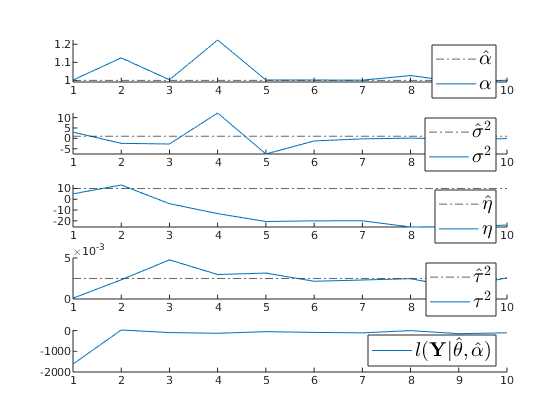

    Sigma = generate_Sigma(theta(:,i+1), s_meas, m);
    alpha(i+1) = (H'/Sigma*H)\(H'/Sigma*Y);
    Z = Y - H*alpha(i+1);
    LogLikelihood(i+1) = -0.5*log(norm(Sigma)) - 0.5*Z'/Sigma*Z;
    
figure
subplot(5,1,1); hold on;
yline(alpha_true,'-.');
plot(alpha)
legend("$\hat{\alpha}$","$\alpha$",'interpreter', 'latex', 'FontSize', 15)
subplot(5,1,2); hold on;
yline(theta_true(1),'-.');
plot(theta(1,:))
legend("$\hat{\sigma}^2$","$\sigma^2$",'interpreter', 'latex', 'FontSize', 15)
subplot(5,1,3); hold on;
yline(theta_true(2),'-.');
plot(theta(2,:))
legend("$\hat{\eta}$","$\eta$",'interpreter', 'latex', 'FontSize', 15)
subplot(5,1,4); hold on;
yline(theta_true(3),'-.');
plot(theta(3,:))
legend("$\hat{\tau}^2$","$\tau^2$",'interpreter', 'latex', 'FontSize', 15)
subplot(5,1,5); hold on;
plot((LogLikelihood))
legend("$l(\mathbf{Y} | \hat\theta,\hat\alpha)$",'interpreter', 'latex', 'FontSize', 15)

## Task 3

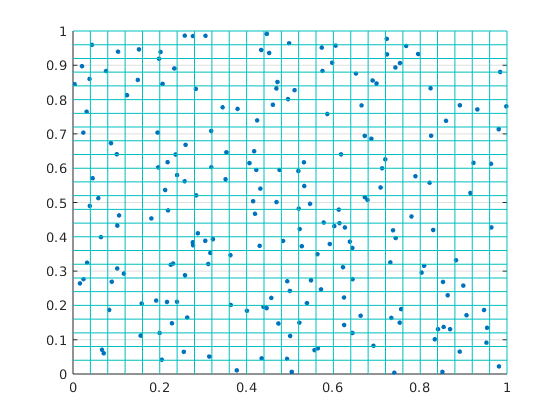

% Estimate s(s).
% C = Cov(i,j), C_0 = Cov(0,i).

grid_size = 25;

figure
plot(s_meas(:,1),s_meas(:,2),'.','MarkerSize',10);
hold on
for i = 1:grid_size
    plot([0 1],[i*1/grid_size i*1/grid_size],'color',[0, 0.75, 0.75],'LineWidth',0.5);
    plot([i*1/grid_size i*1/grid_size], [0 1],'color',[0, 0.75, 0.75],'LineWidth',0.5);
end
grid


% locations = zeros(1,625);
% j=0;
% for i = 1:grid_size:grid_size^2
%     locations(i+j)=1;
%     for j = 1:grid_size
%         locations(i+j)=j+1;
%     end
%     j=0;
% end
% locations = locations(1:end-1)';

s_pred = [(0:0.04:1-0.04)', zeros(grid_size,1)];
for i=1:grid_size-1
    s_pred = [s_pred; (0:0.04:1-0.04)', 0.04*i*ones(grid_size,1)];
end

H_pred = zeros(grid_size^2,1);
Sigma_0 = zeros(grid_size^2,m);
Y_est = zeros(grid_size^2,1);
for i = 1:grid_size^2
    H_pred(i) = (s_pred(i,1) - 0.5) + (s_pred(i,2) - 0.5);
    Sigma_0(i,:) = generate_Sigma_pred(theta,s_pred(i,:),s_meas,m);
    Y_est(i,1) = H_pred(i)*alpha_true + Sigma_0(i,:)*inv(Sigma)*(Y-H*alpha_true);
end

% H_pred has some complex numbers, when the 

% I am not sure of what is Sigma_0 (see last slide).
% Is it the just the covariance of the i-th point?
% Then can be computed with Si=Sj and so it is always sigma squared?




